# Preprocessing Data

Instructions are in the task pane to the left. Complete and submit each task one at a time. Do not edit. This code loads the data.

letterM = readtable("M.txt")

letterM = 41×4 table
    Time       X        Y        P  
    _____    _____    _____    _____

    13734    0.736    0.332    0.026
    13735    0.736    0.333    0.095
    13735    0.736    0.333    0.095
    13749    0.735    0.334    0.284
    13766    0.735    0.328    0.515
    13782    0.735    0.318    0.763
    13799    0.736    0.299    0.983
    13817    0.737    0.284        1
    13832    0.738    0.268        1
    13850    0.738    0.258        1
    13867    0.738    0.253        1
    13883    0.739    0.253        1
    13899    0.739    0.256        1
    13916    0.739    0.268        1
    13933     0.74    0.286        1
    13949    0.742    0.304        1


## Task 1

You can use dot notation to extract, modify, and reassign variables in a table, just as you would with any variable.

`x` `=` `x` `+` `3``;`

`data.XVal` `=` `data.XVal` `+` `3``;`

**TASK1**

Multiply the values in the `X` variable of the table `letter` by the aspect ratio of 1.5. Reassign the result back to `X` so that `letter` contains the corrected data.

**Hint1**

Multiply `letter.X` by `1.5`. Assign the result to `letter.X`.

letterM.X = 1.5*letterM.X;

View the result

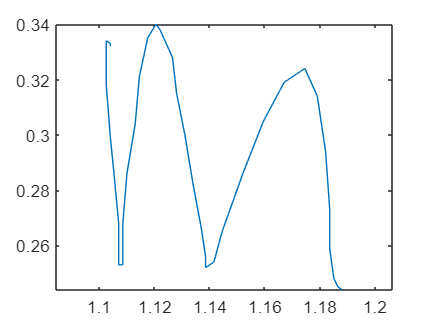

plot(letterM.X,letterM.Y)
axis equal

## Task 2

You can index into variables in a table, just as you would with any variable.

`finalX` `=` `data.XVal``(``end``)``;`

**TASK2**

Shift the `Time` variable of the table `letter` to start at 0 by subtracting the first value from all elements. Divide the result by 1000 to convert to seconds. Reassign the result back to `Time` so that `letter` contains the adjusted data.

**Hint2**

Subtract `letter.Time``(``1``)` from `letter.Time` and divide by 1000. Remember order of operations. Assign the result to `letter.Time`.

letterM.Time = letterM.Time - letterM.Time(1)

letterM = 41×4 table
    Time      X         Y        P  
    ____    ______    _____    _____

      0      1.104    0.332    0.026
      1      1.104    0.333    0.095
      1      1.104    0.333    0.095
     15     1.1025    0.334    0.284
     32     1.1025    0.328    0.515
     48     1.1025    0.318    0.763
     65      1.104    0.299    0.983
     83     1.1055    0.284        1
     98      1.107    0.268        1
    116      1.107    0.258        1
    133      1.107    0.253        1
    149     1.1085    0.253        1
    165     1.1085    0.256        1
    182     1.1085    0.268        1
    199       1.11    0.286        1
    215      1.113    0.304        1


letterM.Time = letterM.Time/1000

letterM = 41×4 table
    Time       X         Y        P  
    _____    ______    _____    _____

        0     1.104    0.332    0.026
    0.001     1.104    0.333    0.095
    0.001     1.104    0.333    0.095
    0.015    1.1025    0.334    0.284
    0.032    1.1025    0.328    0.515
    0.048    1.1025    0.318    0.763
    0.065     1.104    0.299    0.983
    0.083    1.1055    0.284        1
    0.098     1.107    0.268        1
    0.116     1.107    0.258        1
    0.133     1.107    0.253        1
    0.149    1.1085    0.253        1
    0.165    1.1085    0.256        1
    0.182    1.1085    0.268        1
    0.199      1.11    0.286        1
    0.215     1.113    0.304        1


## View the result

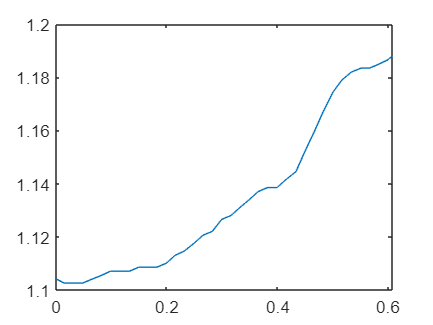

plot(letterM.Time,letterM.X)

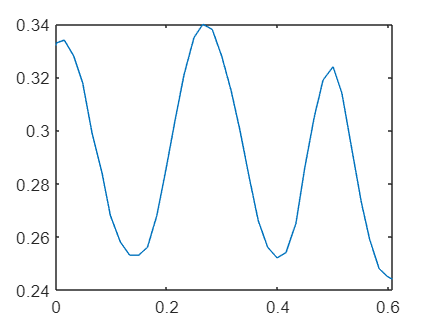

plot(letterM.Time,letterM.Y)

## Further Practice

Check that your code works for `J.txt` and `V.txt` without having to modify anything except the file name.

letterJ = readtable("J.txt")

letterJ = 27×4 table
    Time       X        Y        P  
    _____    _____    _____    _____

    10256    0.402    0.285    0.011
    10263    0.401    0.286    0.079
    10263    0.401    0.286    0.079
    10280    0.398    0.287    0.219
    10296    0.397    0.286     0.29
    10314    0.397    0.278    0.386
    10330      0.4    0.265    0.489
    10332    0.401    0.261    0.515
    10347    0.404    0.245    0.657
    10364    0.408    0.228    0.831
    10379    0.411    0.212        1
    10397     0.41    0.201        1
    10413    0.407    0.194        1
    10431    0.403    0.192        1
    10447    0.395    0.192        1
    10464    0.387    0.195        1


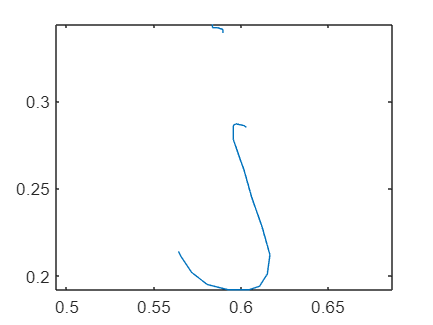

letterJ.X = 1.5*letterJ.X;
plot(letterJ.X,letterJ.Y)
axis equal

letterJ.Time = letterJ.Time - letterJ.Time(1)

letterJ = 27×4 table
    Time      X         Y        P  
    ____    ______    _____    _____

      0      0.603    0.285    0.011
      7     0.6015    0.286    0.079
      7     0.6015    0.286    0.079
     24      0.597    0.287    0.219
     40     0.5955    0.286     0.29
     58     0.5955    0.278    0.386
     74        0.6    0.265    0.489
     76     0.6015    0.261    0.515
     91      0.606    0.245    0.657
    108      0.612    0.228    0.831
    123     0.6165    0.212        1
    141      0.615    0.201        1
    157     0.6105    0.194        1
    175     0.6045    0.192        1
    191     0.5925    0.192        1
    208     0.5805    0.195        1


letterJ.Time = letterJ.Time/1000

letterJ = 27×4 table
    Time       X         Y        P  
    _____    ______    _____    _____

        0     0.603    0.285    0.011
    0.007    0.6015    0.286    0.079
    0.007    0.6015    0.286    0.079
    0.024     0.597    0.287    0.219
     0.04    0.5955    0.286     0.29
    0.058    0.5955    0.278    0.386
    0.074       0.6    0.265    0.489
    0.076    0.6015    0.261    0.515
    0.091     0.606    0.245    0.657
    0.108     0.612    0.228    0.831
    0.123    0.6165    0.212        1
    0.141     0.615    0.201        1
    0.157    0.6105    0.194        1
    0.175    0.6045    0.192        1
    0.191    0.5925    0.192        1
    0.208    0.5805    0.195        1


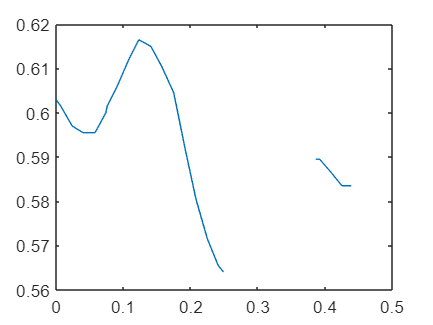

plot(letterJ.Time,letterJ.X)

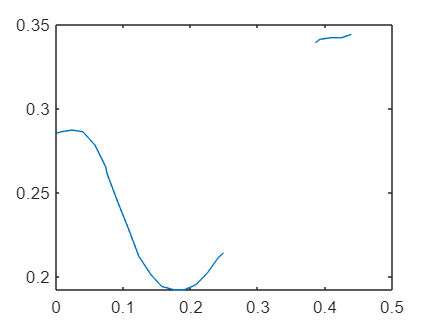

plot(letterJ.Time,letterJ.Y)

letterV = readtable("V.txt")

letterV = 22×4 table
    Time       X        Y        P  
    _____    _____    _____    _____

    13939    0.167    0.255    0.063
    13953    0.167    0.259    0.333
    13953    0.167    0.259    0.333
    13969    0.167     0.26    0.384
    13986    0.167    0.256    0.536
    14003    0.169    0.248    0.622
    14019    0.172    0.232    0.708
    14036    0.175    0.216    0.769
    14052    0.179    0.198    0.856
    14068    0.182    0.186    0.894
    14085    0.184    0.174    0.921
    14102    0.186    0.167     0.94
    14119    0.188    0.168    0.958
    14136    0.189    0.178    0.972
    14152    0.191    0.193    0.974
    14169    0.193    0.218     0.97


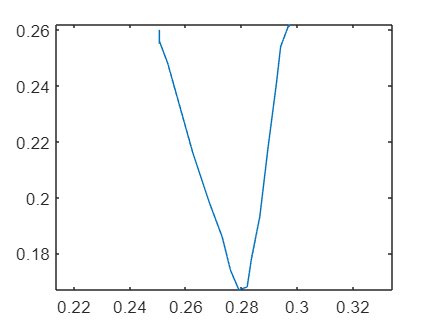

letterV.X = 1.5*letterV.X;
plot(letterV.X,letterV.Y)
axis equal

letterV.Time = letterV.Time - letterV.Time(1)

letterV = 22×4 table
    Time      X         Y        P  
    ____    ______    _____    _____

      0     0.2505    0.255    0.063
     14     0.2505    0.259    0.333
     14     0.2505    0.259    0.333
     30     0.2505     0.26    0.384
     47     0.2505    0.256    0.536
     64     0.2535    0.248    0.622
     80      0.258    0.232    0.708
     97     0.2625    0.216    0.769
    113     0.2685    0.198    0.856
    129      0.273    0.186    0.894
    146      0.276    0.174    0.921
    163      0.279    0.167     0.94
    180      0.282    0.168    0.958
    197     0.2835    0.178    0.972
    213     0.2865    0.193    0.974
    230     0.2895    0.218     0.97


letterV.Time = letterV.Time/1000

letterV = 22×4 table
    Time       X         Y        P  
    _____    ______    _____    _____

        0    0.2505    0.255    0.063
    0.014    0.2505    0.259    0.333
    0.014    0.2505    0.259    0.333
     0.03    0.2505     0.26    0.384
    0.047    0.2505    0.256    0.536
    0.064    0.2535    0.248    0.622
     0.08     0.258    0.232    0.708
    0.097    0.2625    0.216    0.769
    0.113    0.2685    0.198    0.856
    0.129     0.273    0.186    0.894
    0.146     0.276    0.174    0.921
    0.163     0.279    0.167     0.94
     0.18     0.282    0.168    0.958
    0.197    0.2835    0.178    0.972
    0.213    0.2865    0.193    0.974
     0.23    0.2895    0.218     0.97


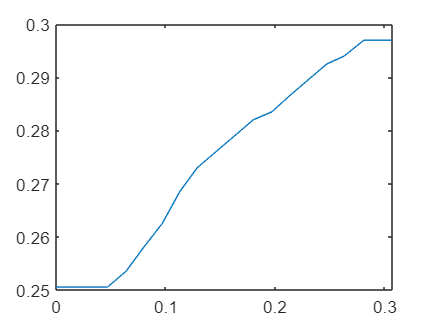

plot(letterV.Time,letterV.X)

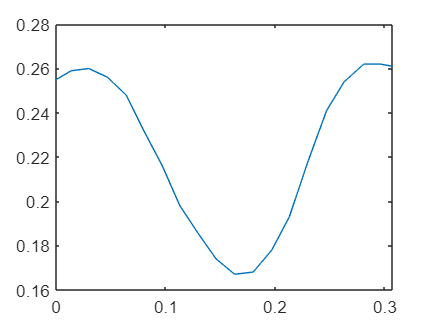

plot(letterV.Time,letterV.Y)